f = @(x,y) sin(y);
n = 5;
x0 = -1;
xn = 2;
y0 = -2;
[y,x] = Euler(f,n,x0,xn,y0);
x_i = x';
y_i = y';
table(x_i,y_i)

ans = 6×2 table
    x_i       y_i  
    ____    _______

      -1         -2
    -0.4    -2.5456
     0.2    -2.8824
     0.8    -3.0362
     1.4    -3.0993
       2    -3.1247


syms t
exactsol = dsolve("Dy == sin(y)","y(-1) = -2")

$$exactsol = 2\,\mathrm{atan}\left({\mathrm{e}}^{t+\log\left(-\tan\left(1\right)\right)+1}\right)$$

exact_sol_i = double(subs(exactsol,t,x))

exact_sol_i =    -2.0000   -2.4640   -2.7595   -2.9301   -3.0252   -3.0777


error_i = abs(exact_sol_i-y);
h = ezplot(exactsol,[x0,xn]);
set(h,"Linewidth",1);
[x_1,y_1] = meshgrid(x0:0.08:xn,-3.5:0.08:y0)

x_1 =    -1.0000   -0.9200   -0.8400   -0.7600   -0.6800   -0.6000   -0.5200   -0.4400   -0.3600   -0.2800   -0.2000   -0.1200   -0.0400    0.0400    0.1200    0.2000    0.2800    0.3600    0.4400    0.5200    0.6000    0.6800    0.7600    0.8400    0.9200    1.0000    1.0800    1.1600    1.2400    1.3200    1.4000    1.4800    1.5600    1.6400    1.7200    1.8000    1.8800    1.9600
   -1.0000   -0.9200   -0.8400   -0.7600   -0.6800   -0.6000   -0.5200   -0.4400   -0.3600   -0.2800   -0.2000   -0.1200   -0.0400    0.0400    0.1200    0.2000    0.2800    0.3600    0.4400    0.5200    0.6000    0.6800    0.7600    0.8400    0.9200    1.0000    1.0800    1.1600    1.2400    1.3200    1.4000    1.4800    1.5600    1.6400    1.7200    1.8000    1.8800    1.9600
   -1.0000   -0.9200   -0.8400   -0.7600   -0.6800   -0.6000   -0.5200   -0.4400   -0.3600   -0.2800   -0.2000   -0.1200   -0.0400    0.0400    0.1200    0.2000    0.2800    0.3600    0.4400    0.5200    0.6000    0.6800    0.7600  

y_1 =    -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000   -3.5000
   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200   -3.4200
   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400   -3.3400  

y_2 = sin(y_1)

y_2 =     0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508    0.3508
    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748    0.2748
    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971    0.1971  

x_2 = ones(size(y_2))

x_2 =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1

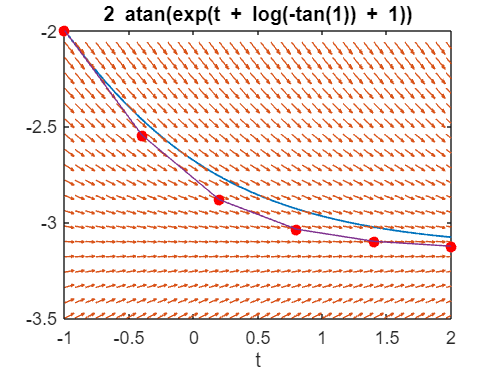

hold on
quiver(x_1,y_1,x_2,y_2)
xlim([x0,xn]);
ylim([-3.5,y0]);
scatter(x,y,"filled","o","r");
plot(x,y);
hold off